filePath = 'C:\Users\thamr\OneDrive\Desktop\mat\dataset3.xlsx';
data = readmatrix(filePath , 'Sheet', 'Hdata2');
dataFull = data;
x = (1:12);

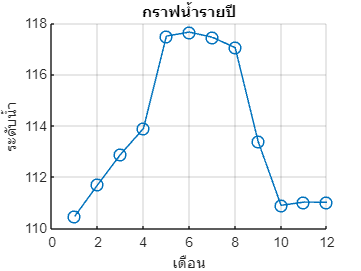



avgPerColumn = mean(data, 1, 'omitnan');
avgPerColumn = avgPerColumn(:,2:end-1);
y = avgPerColumn;
hold on
plot(x, y, 'o-', 'LineWidth', 1, 'MarkerSize', 8);
xlabel('เดือน');
ylabel('ระดับน้ำ');
title('กราฟน้ำรายปี');
grid on;

data = data(:,2:end-1);
maxValues = max(data, [], 1);


fprintf('ค่าสูงสุดแต่ละเดือน:\n');

ค่าสูงสุดแต่ละเดือน:


for i = 1 :size(maxValues, 2)
    fprintf('เดือนที่ %d ค่าสูงสุดเท่ากับ : %.2f\n', i, maxValues(i));
end

เดือนที่ 1 ค่าสูงสุดเท่ากับ : 111.22
เดือนที่ 2 ค่าสูงสุดเท่ากับ : 113.37
เดือนที่ 3 ค่าสูงสุดเท่ากับ : 113.75
เดือนที่ 4 ค่าสูงสุดเท่ากับ : 116.02
เดือนที่ 5 ค่าสูงสุดเท่ากับ : 117.90
เดือนที่ 6 ค่าสูงสุดเท่ากับ : 117.74
เดือนที่ 7 ค่าสูงสุดเท่ากับ : 117.67
เดือนที่ 8 ค่าสูงสุดเท่ากับ : 117.19
เดือนที่ 9 ค่าสูงสุดเท่ากับ : 116.79
เดือนที่ 10 ค่าสูงสุดเท่ากับ : 111.60
เดือนที่ 11 ค่าสูงสุดเท่ากับ : 111.19
เดือนที่ 12 ค่าสูงสุดเท่ากับ : 111.30


remapMax = repmat(maxValues, 31, 1);

for i = 1:size(data,1)
    for j=1:size(data,2)
        areEqual = isequal(remapMax(i,j), data(i,j));
        if areEqual
            fprintf('เดือนที่ %d วันที่ %.f มีลำดับน้ำสูงสุดอยู่ที่ %.2f\n',j,dataFull(i,1),remapMax(i,j));
        end
    end
end

เดือนที่ 6 วันที่ 1 มีลำดับน้ำสูงสุดอยู่ที่ 117.74
เดือนที่ 7 วันที่ 1 มีลำดับน้ำสูงสุดอยู่ที่ 117.67
เดือนที่ 8 วันที่ 1 มีลำดับน้ำสูงสุดอยู่ที่ 117.19
เดือนที่ 9 วันที่ 1 มีลำดับน้ำสูงสุดอยู่ที่ 116.79
เดือนที่ 10 วันที่ 1 มีลำดับน้ำสูงสุดอยู่ที่ 111.60
เดือนที่ 11 วันที่ 2 มีลำดับน้ำสูงสุดอยู่ที่ 111.19
เดือนที่ 5 วันที่ 11 มีลำดับน้ำสูงสุดอยู่ที่ 117.90
เดือนที่ 5 วันที่ 12 มีลำดับน้ำสูงสุดอยู่ที่ 117.90
เดือนที่ 3 วันที่ 20 มีลำดับน้ำสูงสุดอยู่ที่ 113.75
เดือนที่ 12 วันที่ 20 มีลำดับน้ำสูงสุดอยู่ที่ 111.30
เดือนที่ 12 วันที่ 21 มีลำดับน้ำสูงสุดอยู่ที่ 111.30
เดือนที่ 2 วันที่ 25 มีลำดับน้ำสูงสุดอยู่ที่ 113.37
เดือนที่ 1 วันที่ 30 มีลำดับน้ำสูงสุดอยู่ที่ 111.22
เดือนที่ 4 วันที่ 31 มีลำดับน้ำสูงสุดอยู่ที่ 116.02
